% MatLab 2021 compatible

% Macros
ADC_CHANNELS         = 6;
FFT_BATCH_SIZE       = 512;
REGION               = 55;
ADC_SAMPLE_FREQUENCY = 240000;
COLLECT_DATA         = false;

% Declare path to data dir
region_dir = 'C:/Users/evanr/OneDrive - Texas State University/General - GRP-EE4331-ML-Localization-Project/Workspace/Datasets/DataCollectionDay2/Raw';

region_dir = sprintf(region_dir,REGION);

% Hard coded COM port selection
clear com_port
com_port = serialport("COM13",4000000); %, "timeout", 20.0);
% Make region dir
if ~isfolder(region_dir)
    mkdir(region_dir)
end

%Write header to CSV files
csv_header = ["Ch1_1406Hz_Mag", "Ch1_1875Hz_Mag", "Ch1_2343Hz_Mag", "Ch1_2812Hz_Mag", "Ch1_3281Hz_Mag", "Ch1_3750Hz_Mag", "Ch1_4218Hz_Mag", "Ch1_4687Hz_Mag", "Ch1_5156Hz_Mag", "Ch1_5625Hz_Mag", "Ch1_6093Hz_Mag", "Ch1_6562Hz_Mag", "Ch1_7031Hz_Mag", "Ch1_7500Hz_Mag", "Ch1_7968Hz_Mag", "Ch1_8437Hz_Mag", "Ch1_8906Hz_Mag", "Ch1_9375Hz_Mag", "Ch1_9843Hz_Mag", "Ch1_10312Hz_Mag", "Ch1_10781Hz_Mag", "Ch1_11250Hz_Mag", "Ch1_11718Hz_Mag", "Ch1_12187Hz_Mag", "Ch1_12656Hz_Mag", "Ch1_13125Hz_Mag", "Ch1_13593Hz_Mag", "Ch1_14062Hz_Mag", "Ch1_14531Hz_Mag", "Ch1_15000Hz_Mag", "Ch1_15468Hz_Mag", "Ch1_15937Hz_Mag", "Ch1_16406Hz_Mag", "Ch1_16875Hz_Mag", "Ch1_17343Hz_Mag", "Ch1_17812Hz_Mag", "Ch1_18281Hz_Mag", "Ch1_18750Hz_Mag", "Ch1_19218Hz_Mag", "Ch1_19687Hz_Mag", "Ch1_20156Hz_Mag", "Ch1_20625Hz_Mag", "Ch1_21093Hz_Mag", "Ch1_21562Hz_Mag", "Ch1_22031Hz_Mag", "Ch1_22500Hz_Mag", "Ch1_22968Hz_Mag", "Ch1_23437Hz_Mag", "Ch1_23906Hz_Mag", "Ch1_24375Hz_Mag", "Ch1_24843Hz_Mag", "Ch1_25312Hz_Mag", "Ch1_25781Hz_Mag", "Ch1_26250Hz_Mag", "Ch1_26718Hz_Mag", "Ch1_27187Hz_Mag", "Ch1_27656Hz_Mag", "Ch1_28125Hz_Mag", "Ch1_28593Hz_Mag", "Ch1_29062Hz_Mag", "Ch1_29531Hz_Mag", "Ch1_30000Hz_Mag", "Ch1_30468Hz_Mag", "Ch1_30937Hz_Mag", "Ch1_31406Hz_Mag", "Ch1_31875Hz_Mag", "Ch1_32343Hz_Mag", "Ch1_32812Hz_Mag", "Ch1_33281Hz_Mag", "Ch1_33750Hz_Mag", "Ch1_34218Hz_Mag", "Ch1_34687Hz_Mag", "Ch1_35156Hz_Mag", "Ch1_35625Hz_Mag", "Ch1_36093Hz_Mag", "Ch1_36562Hz_Mag", "Ch1_37031Hz_Mag", "Ch1_37500Hz_Mag", "Ch1_37968Hz_Mag", "Ch1_38437Hz_Mag", "Ch1_38906Hz_Mag", "Ch1_39375Hz_Mag", "Ch1_39843Hz_Mag", "Ch1_40312Hz_Mag", "Ch1_40781Hz_Mag", "Ch1_41250Hz_Mag", "Ch1_41718Hz_Mag", "Ch1_42187Hz_Mag", "Ch1_42656Hz_Mag", "Ch1_43125Hz_Mag", "Ch1_43593Hz_Mag", "Ch1_44062Hz_Mag", "Ch1_44531Hz_Mag", "Ch1_45000Hz_Mag", "Ch1_45468Hz_Mag", "Ch1_45937Hz_Mag", "Ch1_46406Hz_Mag", "Ch1_46875Hz_Mag", "Ch1_47343Hz_Mag", "Ch1_47812Hz_Mag", "Ch1_48281Hz_Mag", "Ch1_48750Hz_Mag", "Ch1_49218Hz_Mag", "Ch1_49687Hz_Mag", "Ch1_50156Hz_Mag", "Ch1_50625Hz_Mag", "Ch1_51093Hz_Mag", "Ch1_51562Hz_Mag", "Ch1_52031Hz_Mag", "Ch1_52500Hz_Mag", "Ch1_52968Hz_Mag", "Ch1_53437Hz_Mag", "Ch1_53906Hz_Mag", "Ch1_54375Hz_Mag", "Ch1_54843Hz_Mag", "Ch1_55312Hz_Mag", "Ch1_55781Hz_Mag", "Ch1_56250Hz_Mag", "Ch1_56718Hz_Mag", "Ch1_57187Hz_Mag", "Ch1_57656Hz_Mag", "Ch1_58125Hz_Mag", "Ch1_58593Hz_Mag", "Ch1_59062Hz_Mag", "Ch1_59531Hz_Mag", "Ch1_60000Hz_Mag", "Ch1_60468Hz_Mag", "Ch1_60937Hz_Mag", "Ch1_61406Hz_Mag", "Ch1_61875Hz_Mag", "Ch1_62343Hz_Mag", "Ch1_62812Hz_Mag", "Ch1_63281Hz_Mag", "Ch1_63750Hz_Mag", "Ch1_64218Hz_Mag", "Ch1_64687Hz_Mag", "Ch1_65156Hz_Mag", "Ch1_65625Hz_Mag", "Ch1_66093Hz_Mag", "Ch1_66562Hz_Mag", "Ch1_67031Hz_Mag", "Ch1_67500Hz_Mag", "Ch1_67968Hz_Mag", "Ch1_68437Hz_Mag", "Ch1_68906Hz_Mag", "Ch1_69375Hz_Mag", "Ch1_69843Hz_Mag", "Ch1_70312Hz_Mag", "Ch1_70781Hz_Mag", "Ch1_71250Hz_Mag", "Ch1_71718Hz_Mag", "Ch1_72187Hz_Mag", "Ch1_72656Hz_Mag", "Ch1_73125Hz_Mag", "Ch1_73593Hz_Mag", "Ch1_74062Hz_Mag", "Ch1_74531Hz_Mag", "Ch1_75000Hz_Mag", "Ch1_75468Hz_Mag", "Ch1_75937Hz_Mag", "Ch1_76406Hz_Mag", "Ch1_76875Hz_Mag", "Ch1_77343Hz_Mag", "Ch1_77812Hz_Mag", "Ch1_78281Hz_Mag", "Ch1_78750Hz_Mag", "Ch1_79218Hz_Mag", "Ch1_79687Hz_Mag", "Ch1_80156Hz_Mag", "Ch1_80625Hz_Mag", "Ch1_81093Hz_Mag", "Ch1_81562Hz_Mag", "Ch1_82031Hz_Mag", "Ch1_82500Hz_Mag", "Ch1_82968Hz_Mag", "Ch1_83437Hz_Mag", "Ch1_83906Hz_Mag", "Ch1_84375Hz_Mag", "Ch1_84843Hz_Mag", "Ch1_85312Hz_Mag", "Ch1_85781Hz_Mag", "Ch1_86250Hz_Mag", "Ch1_86718Hz_Mag", "Ch1_87187Hz_Mag", "Ch1_87656Hz_Mag", "Ch1_88125Hz_Mag", "Ch1_88593Hz_Mag", "Ch1_89062Hz_Mag", "Ch1_89531Hz_Mag", "Ch1_90000Hz_Mag", "Ch1_90468Hz_Mag", "Ch1_90937Hz_Mag", "Ch1_91406Hz_Mag", "Ch1_91875Hz_Mag", "Ch1_92343Hz_Mag", "Ch1_92812Hz_Mag", "Ch1_93281Hz_Mag", "Ch1_93750Hz_Mag", "Ch1_94218Hz_Mag", "Ch1_94687Hz_Mag", "Ch1_95156Hz_Mag", "Ch1_95625Hz_Mag", "Ch1_96093Hz_Mag", "Ch1_96562Hz_Mag", "Ch1_97031Hz_Mag", "Ch1_97500Hz_Mag", "Ch1_97968Hz_Mag", "Ch1_98437Hz_Mag", "Ch1_98906Hz_Mag", "Ch1_99375Hz_Mag", "Ch1_99843Hz_Mag", "Ch1_100312Hz_Mag", "Ch1_100781Hz_Mag", "Ch1_101250Hz_Mag", "Ch1_101718Hz_Mag", "Ch1_102187Hz_Mag", "Ch1_102656Hz_Mag", "Ch1_103125Hz_Mag", "Ch1_103593Hz_Mag", "Ch1_104062Hz_Mag", "Ch1_104531Hz_Mag", "Ch1_105000Hz_Mag", "Ch1_105468Hz_Mag", "Ch1_105937Hz_Mag", "Ch1_106406Hz_Mag", "Ch1_106875Hz_Mag", "Ch1_107343Hz_Mag", "Ch1_107812Hz_Mag", "Ch1_108281Hz_Mag", "Ch1_108750Hz_Mag", "Ch1_109218Hz_Mag", "Ch1_109687Hz_Mag", "Ch1_110156Hz_Mag", "Ch1_110625Hz_Mag", "Ch1_111093Hz_Mag", "Ch1_111562Hz_Mag", "Ch1_112031Hz_Mag", "Ch1_112500Hz_Mag", "Ch1_112968Hz_Mag", "Ch1_113437Hz_Mag", "Ch1_113906Hz_Mag", "Ch1_114375Hz_Mag", "Ch1_114843Hz_Mag", "Ch1_115312Hz_Mag", "Ch1_115781Hz_Mag", "Ch1_116250Hz_Mag", "Ch1_116718Hz_Mag", "Ch1_117187Hz_Mag", "Ch1_117656Hz_Mag", "Ch1_118125Hz_Mag", "Ch1_118593Hz_Mag", "Ch1_119062Hz_Mag", "Ch1_119531Hz_Mag", "Ch1_120000Hz_Mag",...
              "Ch2_1406Hz_Mag", "Ch2_1875Hz_Mag", "Ch2_2343Hz_Mag", "Ch2_2812Hz_Mag", "Ch2_3281Hz_Mag", "Ch2_3750Hz_Mag", "Ch2_4218Hz_Mag", "Ch2_4687Hz_Mag", "Ch2_5156Hz_Mag", "Ch2_5625Hz_Mag", "Ch2_6093Hz_Mag", "Ch2_6562Hz_Mag", "Ch2_7031Hz_Mag", "Ch2_7500Hz_Mag", "Ch2_7968Hz_Mag", "Ch2_8437Hz_Mag", "Ch2_8906Hz_Mag", "Ch2_9375Hz_Mag", "Ch2_9843Hz_Mag", "Ch2_10312Hz_Mag", "Ch2_10781Hz_Mag", "Ch2_11250Hz_Mag", "Ch2_11718Hz_Mag", "Ch2_12187Hz_Mag", "Ch2_12656Hz_Mag", "Ch2_13125Hz_Mag", "Ch2_13593Hz_Mag", "Ch2_14062Hz_Mag", "Ch2_14531Hz_Mag", "Ch2_15000Hz_Mag", "Ch2_15468Hz_Mag", "Ch2_15937Hz_Mag", "Ch2_16406Hz_Mag", "Ch2_16875Hz_Mag", "Ch2_17343Hz_Mag", "Ch2_17812Hz_Mag", "Ch2_18281Hz_Mag", "Ch2_18750Hz_Mag", "Ch2_19218Hz_Mag", "Ch2_19687Hz_Mag", "Ch2_20156Hz_Mag", "Ch2_20625Hz_Mag", "Ch2_21093Hz_Mag", "Ch2_21562Hz_Mag", "Ch2_22031Hz_Mag", "Ch2_22500Hz_Mag", "Ch2_22968Hz_Mag", "Ch2_23437Hz_Mag", "Ch2_23906Hz_Mag", "Ch2_24375Hz_Mag", "Ch2_24843Hz_Mag", "Ch2_25312Hz_Mag", "Ch2_25781Hz_Mag", "Ch2_26250Hz_Mag", "Ch2_26718Hz_Mag", "Ch2_27187Hz_Mag", "Ch2_27656Hz_Mag", "Ch2_28125Hz_Mag", "Ch2_28593Hz_Mag", "Ch2_29062Hz_Mag", "Ch2_29531Hz_Mag", "Ch2_30000Hz_Mag", "Ch2_30468Hz_Mag", "Ch2_30937Hz_Mag", "Ch2_31406Hz_Mag", "Ch2_31875Hz_Mag", "Ch2_32343Hz_Mag", "Ch2_32812Hz_Mag", "Ch2_33281Hz_Mag", "Ch2_33750Hz_Mag", "Ch2_34218Hz_Mag", "Ch2_34687Hz_Mag", "Ch2_35156Hz_Mag", "Ch2_35625Hz_Mag", "Ch2_36093Hz_Mag", "Ch2_36562Hz_Mag", "Ch2_37031Hz_Mag", "Ch2_37500Hz_Mag", "Ch2_37968Hz_Mag", "Ch2_38437Hz_Mag", "Ch2_38906Hz_Mag", "Ch2_39375Hz_Mag", "Ch2_39843Hz_Mag", "Ch2_40312Hz_Mag", "Ch2_40781Hz_Mag", "Ch2_41250Hz_Mag", "Ch2_41718Hz_Mag", "Ch2_42187Hz_Mag", "Ch2_42656Hz_Mag", "Ch2_43125Hz_Mag", "Ch2_43593Hz_Mag", "Ch2_44062Hz_Mag", "Ch2_44531Hz_Mag", "Ch2_45000Hz_Mag", "Ch2_45468Hz_Mag", "Ch2_45937Hz_Mag", "Ch2_46406Hz_Mag", "Ch2_46875Hz_Mag", "Ch2_47343Hz_Mag", "Ch2_47812Hz_Mag", "Ch2_48281Hz_Mag", "Ch2_48750Hz_Mag", "Ch2_49218Hz_Mag", "Ch2_49687Hz_Mag", "Ch2_50156Hz_Mag", "Ch2_50625Hz_Mag", "Ch2_51093Hz_Mag", "Ch2_51562Hz_Mag", "Ch2_52031Hz_Mag", "Ch2_52500Hz_Mag", "Ch2_52968Hz_Mag", "Ch2_53437Hz_Mag", "Ch2_53906Hz_Mag", "Ch2_54375Hz_Mag", "Ch2_54843Hz_Mag", "Ch2_55312Hz_Mag", "Ch2_55781Hz_Mag", "Ch2_56250Hz_Mag", "Ch2_56718Hz_Mag", "Ch2_57187Hz_Mag", "Ch2_57656Hz_Mag", "Ch2_58125Hz_Mag", "Ch2_58593Hz_Mag", "Ch2_59062Hz_Mag", "Ch2_59531Hz_Mag", "Ch2_60000Hz_Mag", "Ch2_60468Hz_Mag", "Ch2_60937Hz_Mag", "Ch2_61406Hz_Mag", "Ch2_61875Hz_Mag", "Ch2_62343Hz_Mag", "Ch2_62812Hz_Mag", "Ch2_63281Hz_Mag", "Ch2_63750Hz_Mag", "Ch2_64218Hz_Mag", "Ch2_64687Hz_Mag", "Ch2_65156Hz_Mag", "Ch2_65625Hz_Mag", "Ch2_66093Hz_Mag", "Ch2_66562Hz_Mag", "Ch2_67031Hz_Mag", "Ch2_67500Hz_Mag", "Ch2_67968Hz_Mag", "Ch2_68437Hz_Mag", "Ch2_68906Hz_Mag", "Ch2_69375Hz_Mag", "Ch2_69843Hz_Mag", "Ch2_70312Hz_Mag", "Ch2_70781Hz_Mag", "Ch2_71250Hz_Mag", "Ch2_71718Hz_Mag", "Ch2_72187Hz_Mag", "Ch2_72656Hz_Mag", "Ch2_73125Hz_Mag", "Ch2_73593Hz_Mag", "Ch2_74062Hz_Mag", "Ch2_74531Hz_Mag", "Ch2_75000Hz_Mag", "Ch2_75468Hz_Mag", "Ch2_75937Hz_Mag", "Ch2_76406Hz_Mag", "Ch2_76875Hz_Mag", "Ch2_77343Hz_Mag", "Ch2_77812Hz_Mag", "Ch2_78281Hz_Mag", "Ch2_78750Hz_Mag", "Ch2_79218Hz_Mag", "Ch2_79687Hz_Mag", "Ch2_80156Hz_Mag", "Ch2_80625Hz_Mag", "Ch2_81093Hz_Mag", "Ch2_81562Hz_Mag", "Ch2_82031Hz_Mag", "Ch2_82500Hz_Mag", "Ch2_82968Hz_Mag", "Ch2_83437Hz_Mag", "Ch2_83906Hz_Mag", "Ch2_84375Hz_Mag", "Ch2_84843Hz_Mag", "Ch2_85312Hz_Mag", "Ch2_85781Hz_Mag", "Ch2_86250Hz_Mag", "Ch2_86718Hz_Mag", "Ch2_87187Hz_Mag", "Ch2_87656Hz_Mag", "Ch2_88125Hz_Mag", "Ch2_88593Hz_Mag", "Ch2_89062Hz_Mag", "Ch2_89531Hz_Mag", "Ch2_90000Hz_Mag", "Ch2_90468Hz_Mag", "Ch2_90937Hz_Mag", "Ch2_91406Hz_Mag", "Ch2_91875Hz_Mag", "Ch2_92343Hz_Mag", "Ch2_92812Hz_Mag", "Ch2_93281Hz_Mag", "Ch2_93750Hz_Mag", "Ch2_94218Hz_Mag", "Ch2_94687Hz_Mag", "Ch2_95156Hz_Mag", "Ch2_95625Hz_Mag", "Ch2_96093Hz_Mag", "Ch2_96562Hz_Mag", "Ch2_97031Hz_Mag", "Ch2_97500Hz_Mag", "Ch2_97968Hz_Mag", "Ch2_98437Hz_Mag", "Ch2_98906Hz_Mag", "Ch2_99375Hz_Mag", "Ch2_99843Hz_Mag", "Ch2_100312Hz_Mag", "Ch2_100781Hz_Mag", "Ch2_101250Hz_Mag", "Ch2_101718Hz_Mag", "Ch2_102187Hz_Mag", "Ch2_102656Hz_Mag", "Ch2_103125Hz_Mag", "Ch2_103593Hz_Mag", "Ch2_104062Hz_Mag", "Ch2_104531Hz_Mag", "Ch2_105000Hz_Mag", "Ch2_105468Hz_Mag", "Ch2_105937Hz_Mag", "Ch2_106406Hz_Mag", "Ch2_106875Hz_Mag", "Ch2_107343Hz_Mag", "Ch2_107812Hz_Mag", "Ch2_108281Hz_Mag", "Ch2_108750Hz_Mag", "Ch2_109218Hz_Mag", "Ch2_109687Hz_Mag", "Ch2_110156Hz_Mag", "Ch2_110625Hz_Mag", "Ch2_111093Hz_Mag", "Ch2_111562Hz_Mag", "Ch2_112031Hz_Mag", "Ch2_112500Hz_Mag", "Ch2_112968Hz_Mag", "Ch2_113437Hz_Mag", "Ch2_113906Hz_Mag", "Ch2_114375Hz_Mag", "Ch2_114843Hz_Mag", "Ch2_115312Hz_Mag", "Ch2_115781Hz_Mag", "Ch2_116250Hz_Mag", "Ch2_116718Hz_Mag", "Ch2_117187Hz_Mag", "Ch2_117656Hz_Mag", "Ch2_118125Hz_Mag", "Ch2_118593Hz_Mag", "Ch2_119062Hz_Mag", "Ch2_119531Hz_Mag", "Ch2_120000Hz_Mag",...
              "Ch3_1406Hz_Mag", "Ch3_1875Hz_Mag", "Ch3_2343Hz_Mag", "Ch3_2812Hz_Mag", "Ch3_3281Hz_Mag", "Ch3_3750Hz_Mag", "Ch3_4218Hz_Mag", "Ch3_4687Hz_Mag", "Ch3_5156Hz_Mag", "Ch3_5625Hz_Mag", "Ch3_6093Hz_Mag", "Ch3_6562Hz_Mag", "Ch3_7031Hz_Mag", "Ch3_7500Hz_Mag", "Ch3_7968Hz_Mag", "Ch3_8437Hz_Mag", "Ch3_8906Hz_Mag", "Ch3_9375Hz_Mag", "Ch3_9843Hz_Mag", "Ch3_10312Hz_Mag", "Ch3_10781Hz_Mag", "Ch3_11250Hz_Mag", "Ch3_11718Hz_Mag", "Ch3_12187Hz_Mag", "Ch3_12656Hz_Mag", "Ch3_13125Hz_Mag", "Ch3_13593Hz_Mag", "Ch3_14062Hz_Mag", "Ch3_14531Hz_Mag", "Ch3_15000Hz_Mag", "Ch3_15468Hz_Mag", "Ch3_15937Hz_Mag", "Ch3_16406Hz_Mag", "Ch3_16875Hz_Mag", "Ch3_17343Hz_Mag", "Ch3_17812Hz_Mag", "Ch3_18281Hz_Mag", "Ch3_18750Hz_Mag", "Ch3_19218Hz_Mag", "Ch3_19687Hz_Mag", "Ch3_20156Hz_Mag", "Ch3_20625Hz_Mag", "Ch3_21093Hz_Mag", "Ch3_21562Hz_Mag", "Ch3_22031Hz_Mag", "Ch3_22500Hz_Mag", "Ch3_22968Hz_Mag", "Ch3_23437Hz_Mag", "Ch3_23906Hz_Mag", "Ch3_24375Hz_Mag", "Ch3_24843Hz_Mag", "Ch3_25312Hz_Mag", "Ch3_25781Hz_Mag", "Ch3_26250Hz_Mag", "Ch3_26718Hz_Mag", "Ch3_27187Hz_Mag", "Ch3_27656Hz_Mag", "Ch3_28125Hz_Mag", "Ch3_28593Hz_Mag", "Ch3_29062Hz_Mag", "Ch3_29531Hz_Mag", "Ch3_30000Hz_Mag", "Ch3_30468Hz_Mag", "Ch3_30937Hz_Mag", "Ch3_31406Hz_Mag", "Ch3_31875Hz_Mag", "Ch3_32343Hz_Mag", "Ch3_32812Hz_Mag", "Ch3_33281Hz_Mag", "Ch3_33750Hz_Mag", "Ch3_34218Hz_Mag", "Ch3_34687Hz_Mag", "Ch3_35156Hz_Mag", "Ch3_35625Hz_Mag", "Ch3_36093Hz_Mag", "Ch3_36562Hz_Mag", "Ch3_37031Hz_Mag", "Ch3_37500Hz_Mag", "Ch3_37968Hz_Mag", "Ch3_38437Hz_Mag", "Ch3_38906Hz_Mag", "Ch3_39375Hz_Mag", "Ch3_39843Hz_Mag", "Ch3_40312Hz_Mag", "Ch3_40781Hz_Mag", "Ch3_41250Hz_Mag", "Ch3_41718Hz_Mag", "Ch3_42187Hz_Mag", "Ch3_42656Hz_Mag", "Ch3_43125Hz_Mag", "Ch3_43593Hz_Mag", "Ch3_44062Hz_Mag", "Ch3_44531Hz_Mag", "Ch3_45000Hz_Mag", "Ch3_45468Hz_Mag", "Ch3_45937Hz_Mag", "Ch3_46406Hz_Mag", "Ch3_46875Hz_Mag", "Ch3_47343Hz_Mag", "Ch3_47812Hz_Mag", "Ch3_48281Hz_Mag", "Ch3_48750Hz_Mag", "Ch3_49218Hz_Mag", "Ch3_49687Hz_Mag", "Ch3_50156Hz_Mag", "Ch3_50625Hz_Mag", "Ch3_51093Hz_Mag", "Ch3_51562Hz_Mag", "Ch3_52031Hz_Mag", "Ch3_52500Hz_Mag", "Ch3_52968Hz_Mag", "Ch3_53437Hz_Mag", "Ch3_53906Hz_Mag", "Ch3_54375Hz_Mag", "Ch3_54843Hz_Mag", "Ch3_55312Hz_Mag", "Ch3_55781Hz_Mag", "Ch3_56250Hz_Mag", "Ch3_56718Hz_Mag", "Ch3_57187Hz_Mag", "Ch3_57656Hz_Mag", "Ch3_58125Hz_Mag", "Ch3_58593Hz_Mag", "Ch3_59062Hz_Mag", "Ch3_59531Hz_Mag", "Ch3_60000Hz_Mag", "Ch3_60468Hz_Mag", "Ch3_60937Hz_Mag", "Ch3_61406Hz_Mag", "Ch3_61875Hz_Mag", "Ch3_62343Hz_Mag", "Ch3_62812Hz_Mag", "Ch3_63281Hz_Mag", "Ch3_63750Hz_Mag", "Ch3_64218Hz_Mag", "Ch3_64687Hz_Mag", "Ch3_65156Hz_Mag", "Ch3_65625Hz_Mag", "Ch3_66093Hz_Mag", "Ch3_66562Hz_Mag", "Ch3_67031Hz_Mag", "Ch3_67500Hz_Mag", "Ch3_67968Hz_Mag", "Ch3_68437Hz_Mag", "Ch3_68906Hz_Mag", "Ch3_69375Hz_Mag", "Ch3_69843Hz_Mag", "Ch3_70312Hz_Mag", "Ch3_70781Hz_Mag", "Ch3_71250Hz_Mag", "Ch3_71718Hz_Mag", "Ch3_72187Hz_Mag", "Ch3_72656Hz_Mag", "Ch3_73125Hz_Mag", "Ch3_73593Hz_Mag", "Ch3_74062Hz_Mag", "Ch3_74531Hz_Mag", "Ch3_75000Hz_Mag", "Ch3_75468Hz_Mag", "Ch3_75937Hz_Mag", "Ch3_76406Hz_Mag", "Ch3_76875Hz_Mag", "Ch3_77343Hz_Mag", "Ch3_77812Hz_Mag", "Ch3_78281Hz_Mag", "Ch3_78750Hz_Mag", "Ch3_79218Hz_Mag", "Ch3_79687Hz_Mag", "Ch3_80156Hz_Mag", "Ch3_80625Hz_Mag", "Ch3_81093Hz_Mag", "Ch3_81562Hz_Mag", "Ch3_82031Hz_Mag", "Ch3_82500Hz_Mag", "Ch3_82968Hz_Mag", "Ch3_83437Hz_Mag", "Ch3_83906Hz_Mag", "Ch3_84375Hz_Mag", "Ch3_84843Hz_Mag", "Ch3_85312Hz_Mag", "Ch3_85781Hz_Mag", "Ch3_86250Hz_Mag", "Ch3_86718Hz_Mag", "Ch3_87187Hz_Mag", "Ch3_87656Hz_Mag", "Ch3_88125Hz_Mag", "Ch3_88593Hz_Mag", "Ch3_89062Hz_Mag", "Ch3_89531Hz_Mag", "Ch3_90000Hz_Mag", "Ch3_90468Hz_Mag", "Ch3_90937Hz_Mag", "Ch3_91406Hz_Mag", "Ch3_91875Hz_Mag", "Ch3_92343Hz_Mag", "Ch3_92812Hz_Mag", "Ch3_93281Hz_Mag", "Ch3_93750Hz_Mag", "Ch3_94218Hz_Mag", "Ch3_94687Hz_Mag", "Ch3_95156Hz_Mag", "Ch3_95625Hz_Mag", "Ch3_96093Hz_Mag", "Ch3_96562Hz_Mag", "Ch3_97031Hz_Mag", "Ch3_97500Hz_Mag", "Ch3_97968Hz_Mag", "Ch3_98437Hz_Mag", "Ch3_98906Hz_Mag", "Ch3_99375Hz_Mag", "Ch3_99843Hz_Mag", "Ch3_100312Hz_Mag", "Ch3_100781Hz_Mag", "Ch3_101250Hz_Mag", "Ch3_101718Hz_Mag", "Ch3_102187Hz_Mag", "Ch3_102656Hz_Mag", "Ch3_103125Hz_Mag", "Ch3_103593Hz_Mag", "Ch3_104062Hz_Mag", "Ch3_104531Hz_Mag", "Ch3_105000Hz_Mag", "Ch3_105468Hz_Mag", "Ch3_105937Hz_Mag", "Ch3_106406Hz_Mag", "Ch3_106875Hz_Mag", "Ch3_107343Hz_Mag", "Ch3_107812Hz_Mag", "Ch3_108281Hz_Mag", "Ch3_108750Hz_Mag", "Ch3_109218Hz_Mag", "Ch3_109687Hz_Mag", "Ch3_110156Hz_Mag", "Ch3_110625Hz_Mag", "Ch3_111093Hz_Mag", "Ch3_111562Hz_Mag", "Ch3_112031Hz_Mag", "Ch3_112500Hz_Mag", "Ch3_112968Hz_Mag", "Ch3_113437Hz_Mag", "Ch3_113906Hz_Mag", "Ch3_114375Hz_Mag", "Ch3_114843Hz_Mag", "Ch3_115312Hz_Mag", "Ch3_115781Hz_Mag", "Ch3_116250Hz_Mag", "Ch3_116718Hz_Mag", "Ch3_117187Hz_Mag", "Ch3_117656Hz_Mag", "Ch3_118125Hz_Mag", "Ch3_118593Hz_Mag", "Ch3_119062Hz_Mag", "Ch3_119531Hz_Mag", "Ch3_120000Hz_Mag","Region"]

csv_header = 1×763 string array
    "Ch1_1406Hz_Mag"    "Ch1_1875Hz_Mag"    "Ch1_2343Hz_Mag"    "Ch1_2812Hz_Mag"    "Ch1_3281Hz_Mag"    "Ch1_3750Hz_Mag"    "Ch1_4218Hz_Mag"    "Ch1_4687Hz_Mag"    "Ch1_5156Hz_Mag"    "Ch1_5625Hz_Mag"    "Ch1_6093Hz_Mag"    "Ch1_6562Hz_Mag"    "Ch1_7031Hz_Mag"    "Ch1_7500Hz_Mag"    "Ch1_7968Hz_Mag"    "Ch1_8437Hz_Mag"    "Ch1_8906Hz_Mag"    "Ch1_9375Hz_Mag"    "Ch1_9843Hz_Mag"    "Ch1_10312Hz_Mag"    "Ch1_10781Hz_Mag"    "Ch1_11250Hz_Mag"    "Ch1_11718Hz_Mag"    "Ch1_12187Hz_Mag"    "Ch1_12656Hz_Mag"    "Ch1_13125Hz_Mag"    "Ch1_13593Hz_Mag"    "Ch1_14062Hz_Mag"    "Ch1_14531Hz_Mag"    "Ch1_15000Hz_Mag"    "Ch1_15468Hz_Mag"    "Ch1_15937Hz_Mag"    "Ch1_16406Hz_Mag"    "Ch1_16875Hz_Mag"    "Ch1_17343Hz_Mag"    "Ch1_17812Hz_Mag"    "Ch1_18281Hz_Mag"    "Ch1_18750Hz_Mag"    "Ch1_19218Hz_Mag"    "Ch1_19687Hz_Mag"    "Ch1_20156Hz_Mag"    "Ch1_20625Hz_Mag"    "Ch1_21093Hz_Mag"    "Ch1_21562Hz_Mag"    "Ch1_22031Hz_Mag"    "Ch1_22500Hz_Mag"    "Ch1_22968Hz_Mag"

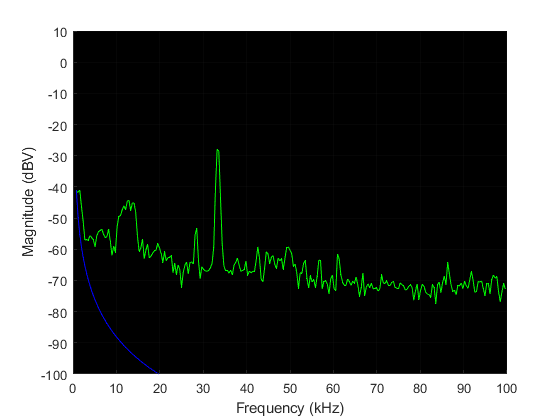


reg_dir = sprintf(strcat(region_dir,"/Region_%d_Data.csv"),REGION);

try
    writematrix(csv_header,reg_dir)
catch
    disp("Error writing header")
end

% Setup figure for displaying fft data.
figure;
ylim([-100 10]);
xlabel("Frequency (kHz)");
ylabel("Magnitude (dBV)");
title("")
set(gcf,"Visible","on")
set(gca,'Color','k')

x_freqs = 2 * 200/(FFT_BATCH_SIZE):200/(FFT_BATCH_SIZE):100 - 200/(FFT_BATCH_SIZE);
start_bytes = 0;

% Init variables
noise_floor = zeros(1, FFT_BATCH_SIZE / 2) - 100;
noise_floor_samples = 0;
noise_floor_offset_db = 6;

while ( 1 )
    %sync with data
    start_bytes = 0;
    while (start_bytes < 4)
        start_byte = read( com_port, 1, "uint8" );
        if ( start_byte == 0x55 )
            start_bytes = start_bytes + 1;
        else
            start_bytes = 0;
        end
    end
    
    % Get data from UART
    fft_data  = read( com_port, ADC_CHANNELS * FFT_BATCH_SIZE / 2, "single" );
    %fft_one   = fft_data(1:256);
    %fft_two   = fft_data(257:512);
    fft_three = fft_data(513:768);
    fft_four = fft_data(769:1024);
    fft_five = fft_data(1025:1280);
    %fft_six  = fft_data(1281:1536);
   
    if COLLECT_DATA
        % Write channel data to CSV
        row = [fft_three(3:256),fft_four(3:256),fft_five(3:256),REGION];
        writematrix(row,reg_dir,"WriteMode","append");
    end

    %if ( noise_floor_samples < 20 )
    %   for index = 1 : FFT_BATCH_SIZE / 2
    %       if fft_one(index) > noise_floor(index)
    %           noise_floor(index) = fft_one(index);
    %       end
    %       if fft_two(index) > noise_floor(index)
    %           noise_floor(index) = fft_two(index);
    %       end
    %   end        
    %   noise_floor_samples = noise_floor_samples + 1;
    %end
    
    cla;
    hold on
    grid on
    
    %plot( x_freqs, fft_one(3:256), "-r"); 
    %plot( x_freqs, fft_two(3:256), "-b");
    plot( x_freqs, fft_three(3:256), "-g"); 
    plot( x_freqs, fft_four(3:256), "-m");
    plot( x_freqs, fft_five(3:256), "-b"); 
    %plot( x_freqs, fft_six(3:256), "-y"); 
    %plot( x_freqs, noise_floor(3:256) + 6, "--k");

    drawnow;
end


clear com_port